addpath('./Function');
addpath('./Data');

t = table();
for i = 1:10
    i
    [model, train_accr, test_accr, cross_accr, train_word, test_word] = SubjectLDAAnalysis(i);
    train_word = {train_word};
    test_word = {test_word};
    t = [t;table(train_accr, test_accr, cross_accr, train_word, test_word)];
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

writetable(t, 'subject-data.csv');

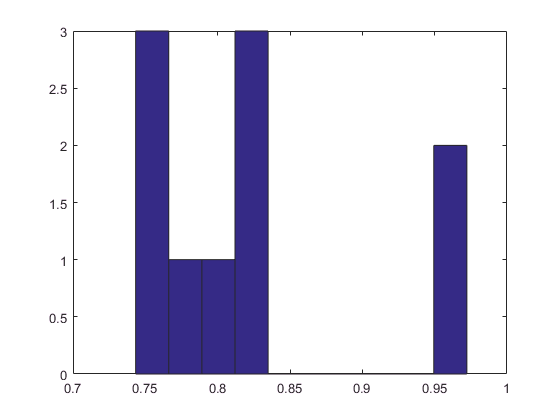

hist(t.test_accr);